RESIDE 图像去雾数据集

- 下载地址: [https://hyper.ai/datasets/18179](https://hyper.ai/datasets/18179)

## 图像预处理

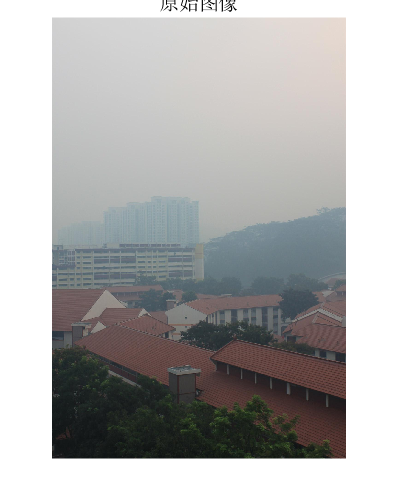

clear;

img_name = './res/SGP_Bing_085.jpeg';

I = double(imread(img_name))/255;  % 归一化
figure,imshow(I);title("原始图像");

## 暗原色图

求取暗原色的公式：


$$$$
J_{dark}(x) = \min_{y \in (r,g,b)}(\min _{y\in\Omega_x}(J_c(y)))
$$$$


$$J_c$$为J的R,G,B三通道中的一个颜色通道，$$\Omega_x$$是以x为中心的局部区域。

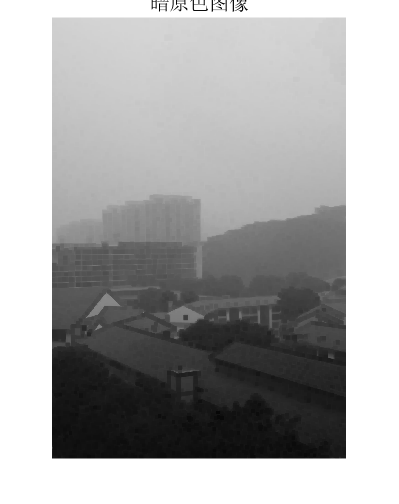

[h,w,c] = size(I);  % 求出图像的高、宽、通道（RGB,3通道）
win_size = 7;
img_size = w*h;
dehaze = zeros(img_size*c,1);
dehaze = reshape(dehaze,h,w,c);


win_dark = zeros(img_size,1);
for cc=1:img_size
    win_dark(cc)=1;
end
win_dark = reshape(win_dark,h,w);

% darkchannel
for j = 1+win_size:w-win_size
    for i = 1+win_size:h-win_size
        m_pos_min = min(I(i,j,:));  % 在局部块中心最小值，R、G、B三通道中的最小分量，因为用的是15*15的，中心（8，8）
        
        % win_size*win_size 区域里面最小滤波
        for n = j-win_size : j+win_size
            for m = i-win_size : i+win_size
                if(win_dark(m,n) > m_pos_min)
                    win_dark(m,n) = m_pos_min;
                end
            end
        end
    end
end

figure,imshow(win_dark);title("暗原色图像");

## 透过率估计

雾天图像退化模型


$$$$
I(x)=J(x)*t(x)+A(1-t(x))
$$$$


假设大气光成分A已知，在局部区域$\Omega_x$内，透过率保持一致


$$$$
\min (\min_{y \in \Omega_x} (\frac{I_c(y)}{A_c})) = t(x) \min_c ( \min _{y \in \Omega_x}  (\frac{I_c(y)}{A_c})) + (1-t(x))
$$$$


有已知无雾图像的暗原色值很小，接近0，且  $$A \ne 0$$。


$$$$
t(x) = 1 - \min _c ( \min _{y \in \Omega_x}( \frac { I_c(y) } {  A_c}  ) )
$$$$


$$\min_c(\min _{y \in \Omega_x}( \frac { I_c(y) } {  A_c}  ))$$正好是用A归一化的带雾图像的暗原色。

考虑空间透视现象，彻底移除雾会使图像看起来不真实，引进一个常数ω(0＜ω ≤1)，有针对性的保留一部分遥远景物的雾。


$$$$
t(x) = 1 - \omega\min _c ( \min _{y \in \Omega_x}( \frac { I_c(y) } {  A_c}  ) )
$$$$


实验表明：一般浓雾越大，ω的值越大，越接近1；薄雾情况下ω偏下，在0.7左右。

文中选取0.8。

% 每个点都需要计算
for cc=1:img_size
    win_dark(cc) = 1-win_dark(cc)*0.8;
end

## 无雾图像复原

首先选取暗原色中亮度最高的0.1%像素，并把它们在输入图像I中对应的最大亮度值，最为大气光A的估计值。A不一定是图像中最亮的值。


$$$$
J(x) = \frac { I(x) - (1-t_{max}(x) )A} { t_{max}(x) }
$$$$


其中：


$$$$
t_{max}(x)=  \max (t(x),t0)
$$$$


t0是透过率的下限值

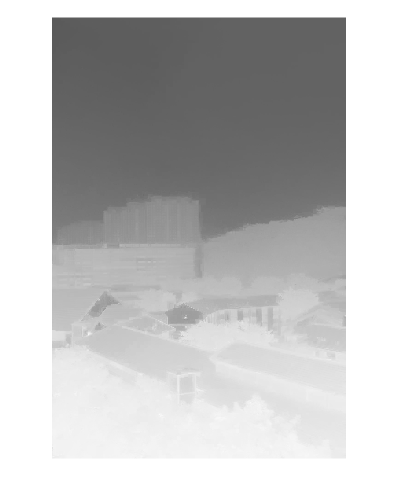

win_b = zeros(img_size,1);
for ci=1:h
    for cj=1:w
        if(rem(ci-8,15) < 1)
            if(rem(cj-8,15) < 1)
                win_b(ci*w + cj) = win_dark(ci*w +cj);  % 前8行，前8列，以及行列均为15的倍数的点
            end
        end
    end
end

neb_size = 9;
win_size = 1;
epsilon = 0.0000001;
indsM = reshape([1:img_size],h,w);
tlen = img_size * neb_size^2;
row_inds = zeros(tlen,1);
col_inds = zeros(tlen,1);
vals = zeros(tlen,1);
len=0;
for j=1+win_size : w-win_size
    for i=1+win_size : h-win_size
        if(rem(ci-8,15)<1)
            if(rem(cj-8,15)<1)
                continue;
            end
        end

        win_inds = indsM(i-win_size:i+win_size,j-win_size:j+win_size);
        win_inds = win_inds(:);
        winI = I(i-win_size:i+win_size,j-win_size:j+win_size,:);
        winI = reshape(winI,neb_size,c);
        win_mu = mean(winI,1)';
        win_var = inv(winI'*winI/neb_size-win_mu*win_mu'+epsilon/neb_size*eye(c));
        winI = winI - repmat(win_mu',neb_size,1);
        tvals = (1+winI*win_var*winI')/neb_size;
    
        row_inds(1+len:neb_size^2+len) = reshape(repmat(win_inds,1,neb_size),...
            neb_size^2,1);
        col_inds(1+len:neb_size^2+len) = reshape(repmat(win_inds',neb_size,1),...
            neb_size^2,1);
        vals(1+len:neb_size^2+len) = tvals(:);
        len = len + neb_size ^ 2;
    end
end

vals = vals(1:len);
row_inds = row_inds(1:len);
col_inds =col_inds(1:len);
A = sparse(row_inds,col_inds,vals,img_size,img_size);
sumA = sum(A,2);
A = spdiags(sumA(:),0,img_size,img_size) - A;

% 创建稀疏矩阵
D = spdiags(win_b(:),0,img_size,img_size);
lambda = 1;
x = (A + lambda*D)\(lambda*win_b(:).*win_b(:));
% 去掉0-1范围以外的数
alpha = max(min(reshape(x,h,w),1),0);

figure,imshow(alpha);

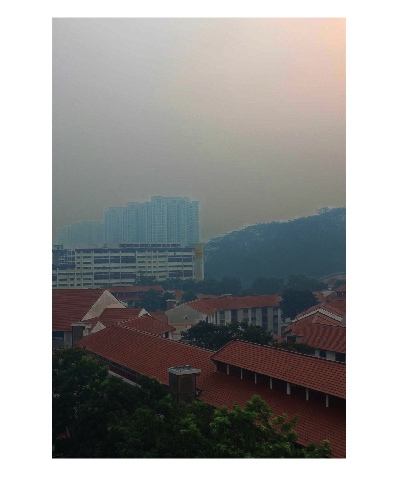


A = 220/255;
for i = 1:c
    for j = 1:h
        for l = 1:w
            dehaze(j,l,i) = (I(j,l,i)-A)/alpha(j,l) + A;
        end
    end
end

figure,imshow(dehaze);